# Assignment Lecture04

**윤지상_미래자동차공학과_2019092115**

## Correlation: Exercise 1

% test
a = randn(15, 1);
b = randn(15, 1);

% cal corr and cosine corr
[r, c] = corrAndCosine(a, b);

fprintf('Calculated Pearson correlation: %f\n', r);

Calculated Pearson correlation: 0.126032


fprintf('Calculated Cosine similarity: %f\n', c);

Calculated Cosine similarity: 0.098094


fprintf('MATLAB corr function: %f\n', corr(a, b));

MATLAB corr function: 0.126032



%%%%%%%%%%%%%% ToDo %%%%%%%%%%%%%%
function [cor, cos] = corrAndCosine(x, y)
    num = dot(x, y); %neumarator
    den = norm(x) * norm(y); %denominator
    cos = num / den;

    xm = x - mean(x);
    ym = y - mean(y);
    num = dot(xm, ym);
    den = norm(xm) * norm(ym);
    cor = num / den;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Correlation: Exercise 2

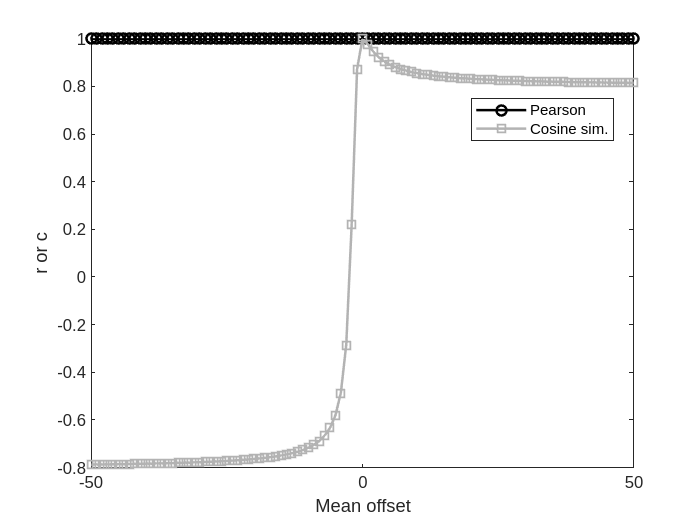

% Define the variables
a = 0:3; 
offsets = -50:50; 

results = zeros(length(offsets), 2);

% Define the corrAndCosine function if it's not already defined
% Please ensure that the corrAndCosine function is defined in MATLAB as shown previously

for i = 1:length(offsets)
    [cor, cos] = corrAndCosine2(a, a + offsets(i));
    results(i, :) = [cor, cos];
end

figure; 
plot(offsets, results, 'LineWidth', 1.5); 
hold on; 
h = gca; 
h.Children(1).Color = [0.7, 0.7, 0.7]; 
h.Children(1).Marker = 's'; 
h.Children(2).Color = 'k'; 
h.Children(2).Marker = 'o'; 

xlabel('Mean offset');
ylabel('r or c');
legend('Pearson', 'Cosine sim.', 'Location', 'Best');

print('Figure_03_02','-dpng','-r300'); % Saves the figure as a PNG with 300 DPI



%%%%%%%%%%%%%% ToDo %%%%%%%%%%%%%%
function [cor, cos] = corrAndCosine2(x, y)
    num = dot(x, y); 
    den = norm(x)*norm(y); 
    cos = num / den;

    xm = x - mean(x);
    ym = y - mean(y);
    num = dot(xm, ym); 
    den = norm(xm)*norm(ym);
    cor = num / den;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Filtering and Feature Detection Exercise 3

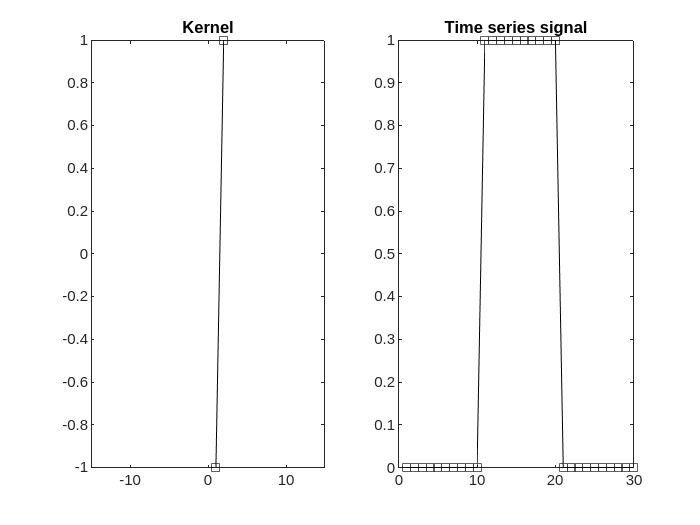

kernel = [-1, 1];

signal = zeros(1, 30);
signal(11:20) = 1;

subplot(1,2,1);
plot(kernel, 'ks-'); title('Kernel'); xlim([-15, 15]);

subplot(1,2,2);
plot(signal, 'ks-'); title('Time series signal');

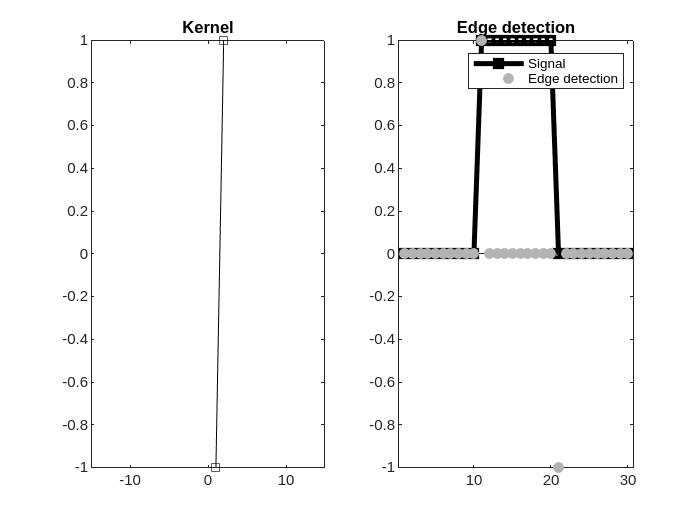


featureMap = zeros(1, length(signal));

%%%%%%%%%%%%%% ToDo %%%%%%%%%%%%%%

for t = 2:length(signal)-1
    featureMap(t) = dot(kernel, signal(t-1:t));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;
subplot(1,2,1);
plot(kernel, 'ks-'); title('Kernel'); xlim([-15, 15]);

subplot(1,2,2);
plot(signal, 'ks-', 'LineWidth', 3); hold on;
stem(featureMap, 'filled', 'LineStyle', 'none', 'Marker', 'o', 'MarkerFaceColor', [.7 .7 .7], 'MarkerEdgeColor', [.7 .7 .7]);
title('Edge detection'); legend('Signal', 'Edge detection');
hold off;

## k-means Exercise 4

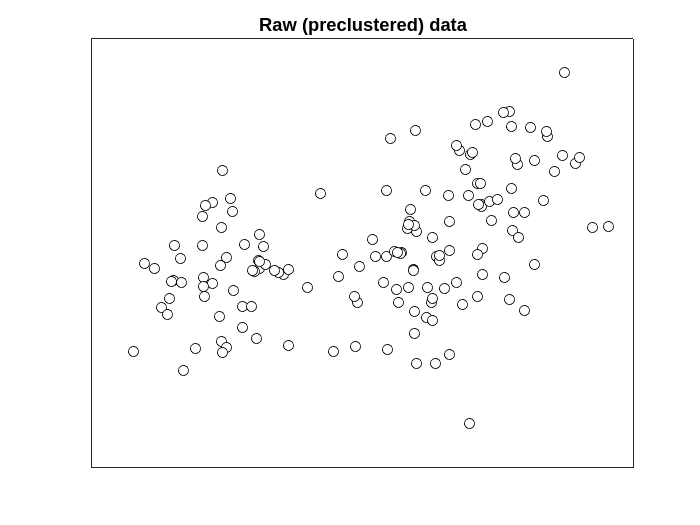

nPerClust = 50;

% Blur around centroid (std units)
blur = 1;

% XY centroid locations
A = [  1, 1 ];
B = [ -3, 1 ];
C = [  3, 3 ];

% Generate data
a = [ A(1)+randn(nPerClust,1)*blur , A(2)+randn(nPerClust,1)*blur ];
b = [ B(1)+randn(nPerClust,1)*blur , B(2)+randn(nPerClust,1)*blur ];
c = [ C(1)+randn(nPerClust,1)*blur , C(2)+randn(nPerClust,1)*blur ];

% Concatenate into a matrix
data = [a; b; c];


% Plot data
figure;
plot(data(:,1), data(:,2), 'ko', 'MarkerFaceColor', 'w');
title('Raw (preclustered) data');
xticks([]);
yticks([]);

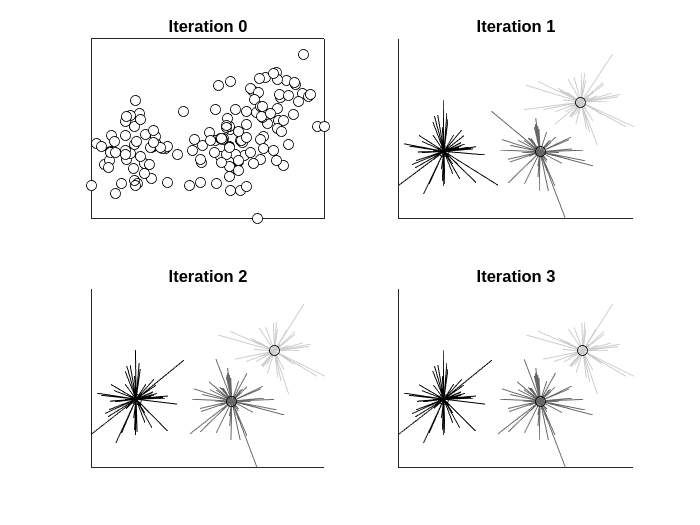


% Number of clusters
k = 3;

% Randomly select cluster centers from the data
ridx = randperm(size(data, 1), k);
centroids = data(ridx, :);

% Setup the figure
figure;
lineColors = [0, 0, 0; .4, .4, .4; .8, .8, .8]; % Different shades of gray for each cluster

% Plot data with initial random cluster centroids
subplot(2, 2, 1);
plot(data(:, 1), data(:, 2), 'ko', 'MarkerFaceColor', 'w'); hold on;
plot(centroids(:, 1), centroids(:, 2), 'ko'); hold off;
title('Iteration 0');
set(gca, 'XTick', [], 'YTick', []);

% Loop over iterations
for iteri = 1:3
    
    %%%%%%%%%%%%%% ToDo %%%%%%%%%%%%%%

    % Step 1: Compute distances from each point to each centroid
    dists = zeros(size(data, 1), k);

    for ci = 1:k
        dists(:, ci) = sum((data - centroids(ci, :)).^2, 2);
    end
    
    % Step 2: Assign to group based on minimum distance
    [minDists, groupidx] = min(dists, [], 2);
    
    % Step 3: Recompute centroids
    for i = 1:k
        centroids(i, :) = mean(data(groupidx == i, :), 1); 
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % Plotting
    subplot(2, 2, iteri+1);
    hold on;
    for i = 1:length(data)
        plot([data(i, 1), centroids(groupidx(i), 1)], [data(i, 2), centroids(groupidx(i), 2)], 'Color', lineColors(groupidx(i), :));
    end
    plot(centroids(:, 1), centroids(:, 2), 'ko');
    hold off;
    title(sprintf('Iteration %d', iteri));
    set(gca, 'XTick', [], 'YTick', []);
end